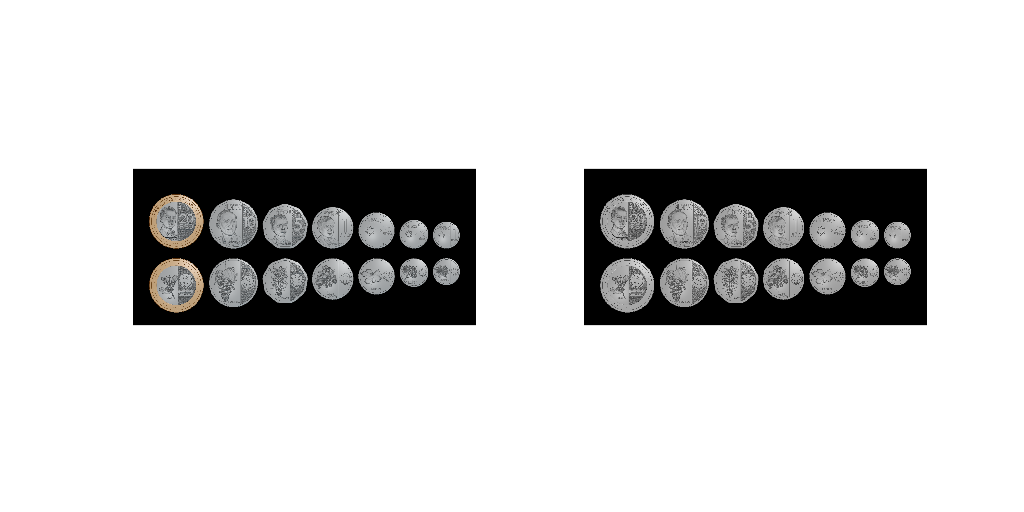

%% Open an image and convert to grayscale
I = imread('NGCCoins.png');
Igray = rgb2gray(I);
figure('Position', [200, 200, 1024, 512]);
subplot(1,2,1); imshow(I);
subplot(1,2,2); imshow(Igray);

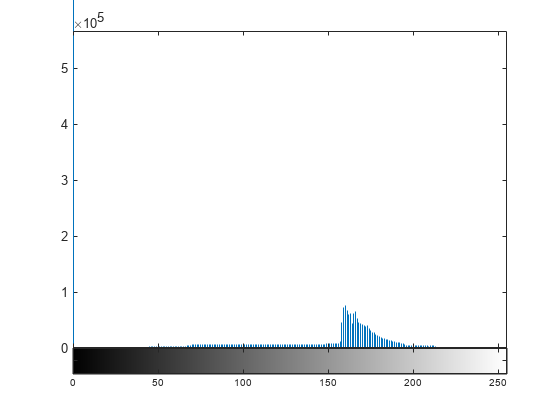

%% Binarize the image by choosing thresholds on the histogram
figure; imhist (Igray);

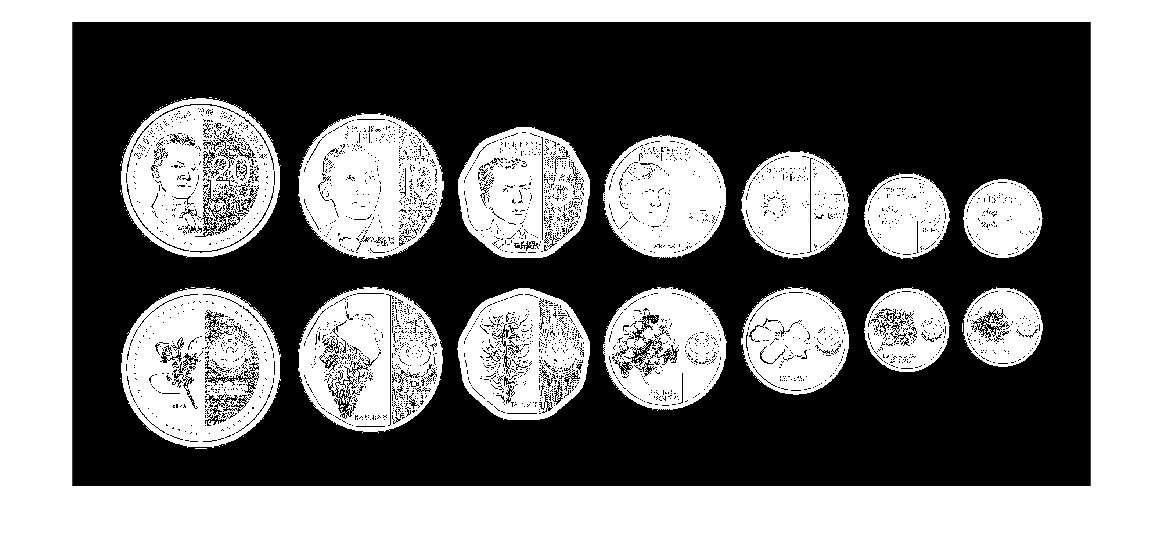

BW= and(Igray < 220, Igray>100); %you may change these tresholds
figure('Position', [200, 200, 1024, 512]); imshow(BW);

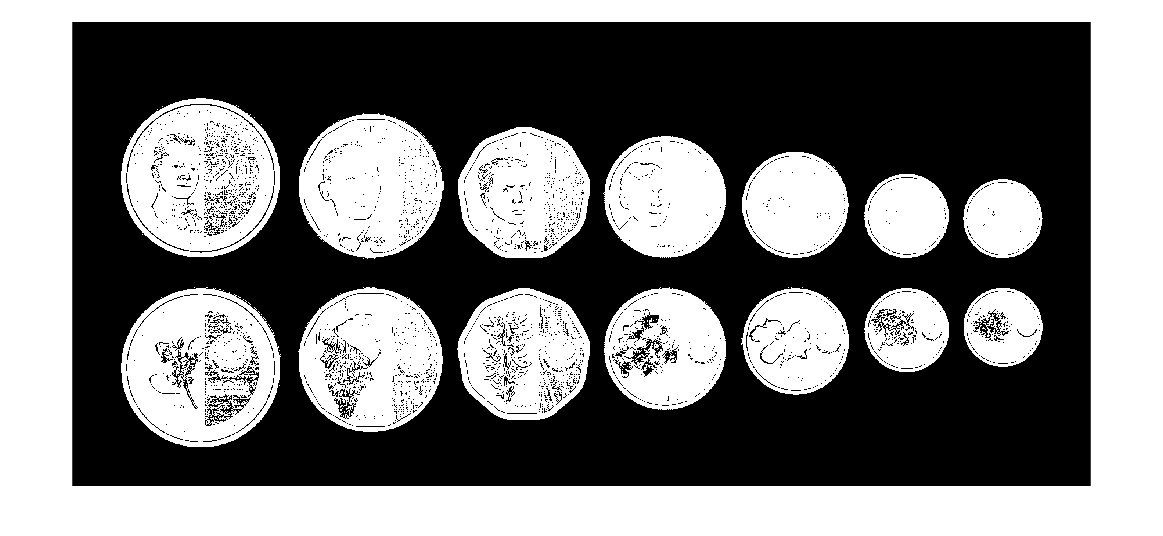

%% Get rid of the small "dusts"
BW2 = bwmorph(BW,"majority");
figure('Position', [200, 200, 1024, 512]); imshow(BW2);

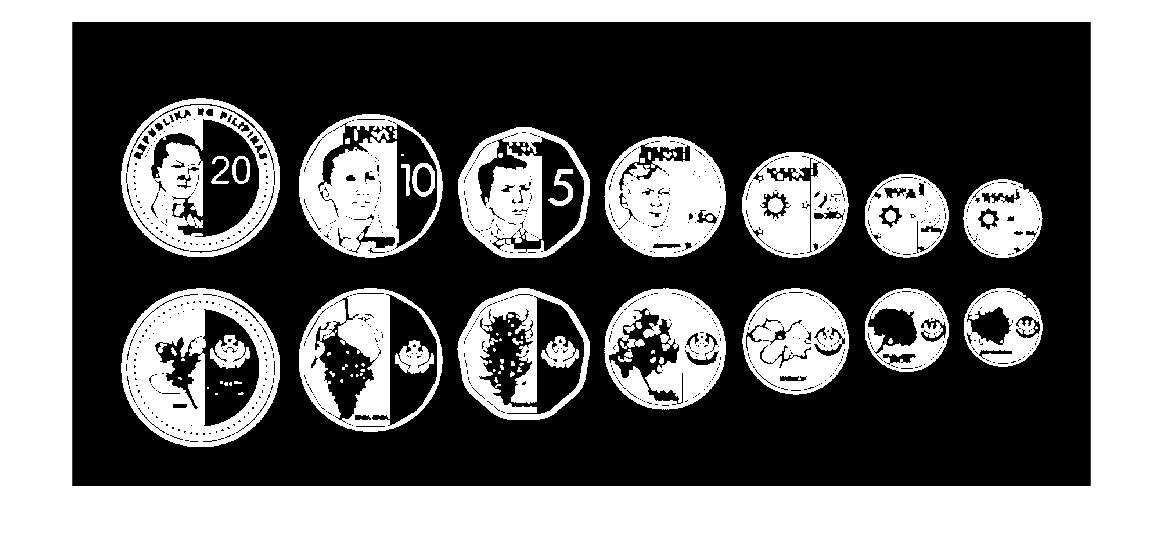

SE = strel("disk",5);
figure;
BW3 = imopen(BW,SE);imshow(BW3); 

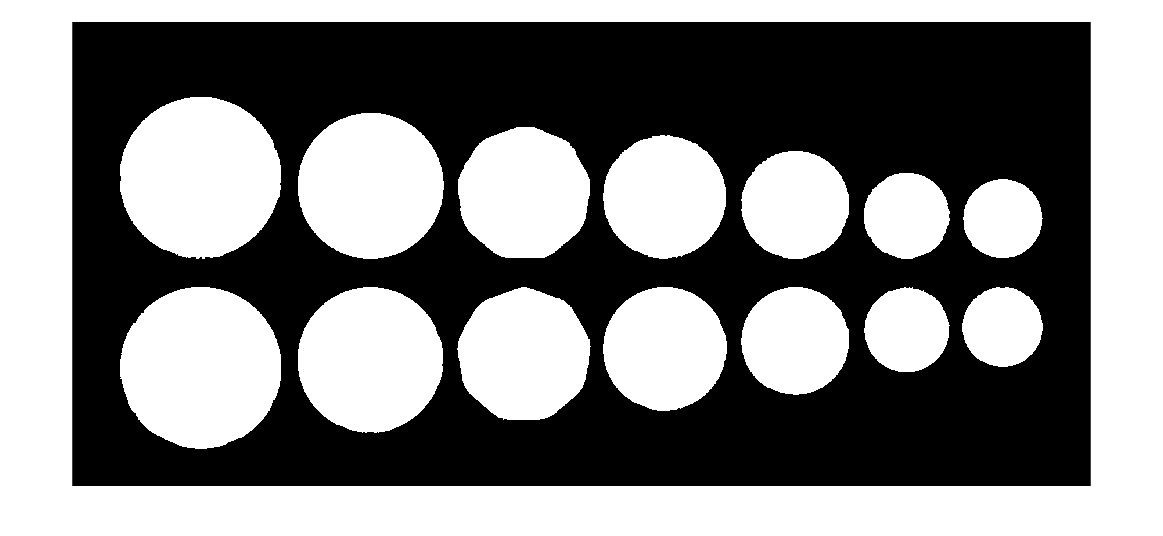

figure;
BW4 = imclose(BW,SE); imshow(BW4);

%% Demo on Regionprops
J = bwlabel(BW4);
figure; imagesc(J); colorbar;
features = regionprops(J, "Area","Eccentricity","Perimeter","Centroid","BoundingBox")

features = 14×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    Eccentricity
    Perimeter


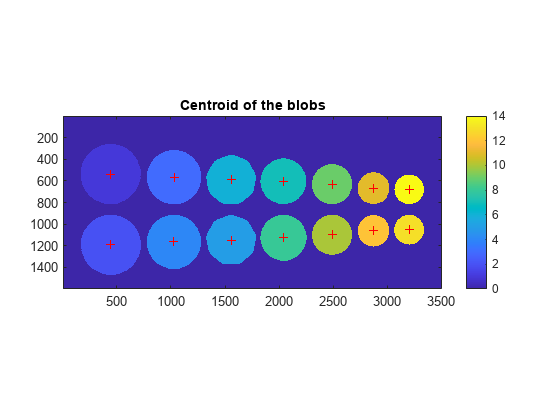


% Put label number on Centroid of Blobs
Centroid = cat(1,features.Centroid);
hold on;
plot(Centroid(:,1),Centroid(:,2),'r+'); axis image; 
title('Centroid of the blobs');

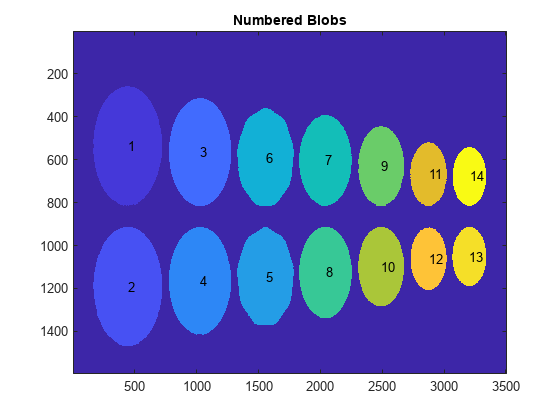

%% Put label numbers on Centroid of blobs
figure; imagesc(J); title('Numbered Blobs'); hold on;
for i = 1:size(Centroid,1)
 text(Centroid(i,1), Centroid(i,2), num2str(i));
end

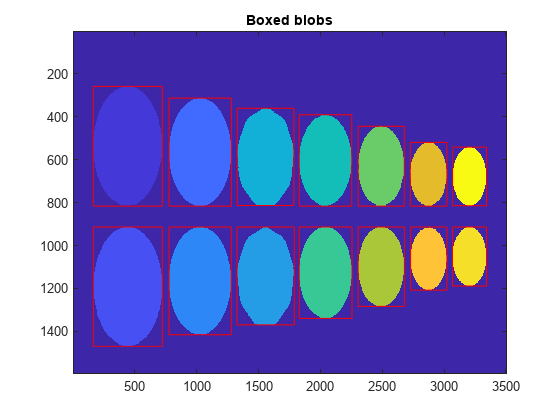


%% Put bounding boxes around each blob
figure; imagesc(J); title('Boxed blobs'); hold on;
bb = cat(1,features.BoundingBox);
for i = 1:size(features,1)
 rectangle('Position',bb(i,:),'EdgeColor','r');
end

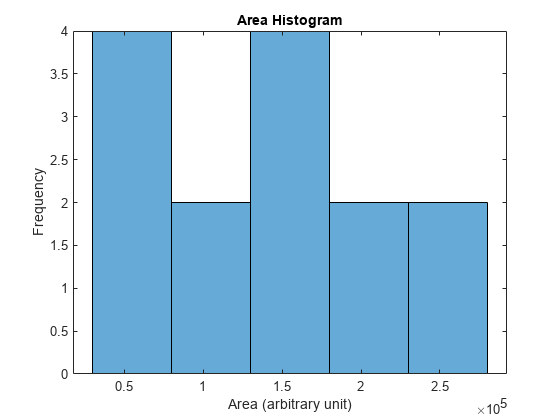

BWL1 = logical(J); 
features = regionprops(BWL1,"Area","Eccentricity","Perimeter","Centroid","BoundingBox");
allarea = cat(1,features.Area);
allperimeter = cat(1,features.Perimeter);
alleccentricity = cat(1,features.Eccentricity);

figure; histogram(allarea,5); title('Area Histogram'); xlabel('Area (arbitrary unit)'); ylabel('Frequency');

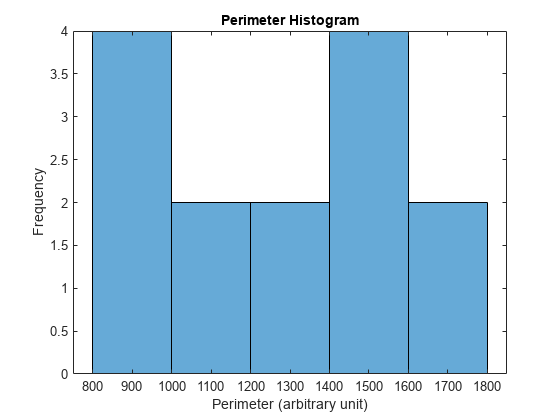

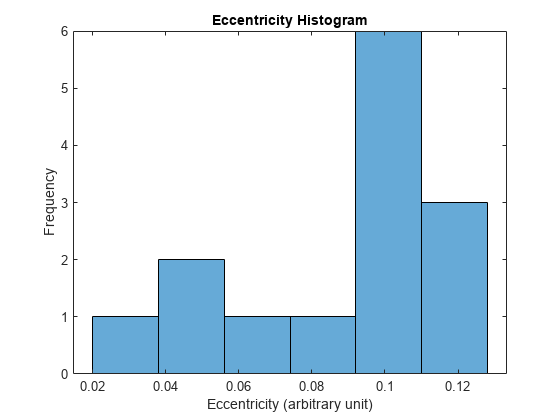

figure; histogram(allperimeter,5); title('Perimeter Histogram'); xlabel('Perimeter (arbitrary unit)'); ylabel('Frequency');